This is NOT EXACT. It has exadderated features to match the (mysterious) graphs in Griffith's Introduction to Quantum Mechanics, and Townsend's A Modern Approach to Quantum Mechanics

x = linspace(-8,8)' ;
m = 1.1 ; w = 7.1; n = 1 ;
figure;
for n = 0:7
    for i=1: length (x)
        herm=sqrt(m*w/(7))*x(i);
        newn=n;
        if n ==0
            H = 0.8 ;
        elseif n == 1
            H = 2*herm;
        elseif n ==2
            H = 4*(herm)^2 -2;
        elseif n == 3
            H = 8* (herm)^3 -12*herm;
        elseif n ==4
            H = 16*(herm)^4 -(48*(herm)^2)+12;
        elseif n ==5
            H =(1024*herm^(10)-23040*(herm)^8+161280*(herm)^6-403200*(herm)^4+302400*(herm)^2-30240)/1000;
        elseif n == 6
            H =(1024*(herm)^20 - 97280*(herm)^18 + 3720960*(herm)^16 - 74419200*(herm)^14 + 846518400*(herm)^12 - 5587021440*(herm)^10 + 20951330400*(herm)^8 - 41902660800*(herm)^6 + 39283744500*(herm)^4 - 13094581500*(herm)^2 + 654729075)*1000;
            newn=20;
        elseif n==7
            H =(33554499)*(33554432*herm^50 - 20552089600*herm^48 + 5795689267200*herm^46 - 999756398592000*herm^44 + 118221194133504000*herm^42 - 10178844814894694400*herm^40 + 661624912968155136000*herm^38 - 33223022415472361472000*herm^36 + 1308156507609224232960000*herm^34 - 40770877820487488593920000*herm^32 + 1011117769948089717129216000*herm^30 - 19992555905791773952327680000*herm^28 + 314882755516220439749160960000*herm^26 - 3936034443952755496864512000000*herm^24 + 38798053804677161326235904000000*herm^22 - 298745014296014142212016460800000*herm^20 + 1773798522382583969383847736000000*herm^18 - 7982093350721627862227314812000000*herm^16 + 26606977835738759540757716040000000*herm^14 - 63716710080321766268656635780000000*herm^12 + 105132571632530914343283449037000000*herm^10 - 112642041034854551082089409682500000 *herm^8 + 71681298840361987052238715252500000 *herm^6 - 23374336578378908821382189756250000 *herm^4 + 2921792072297363602672773719531250*herm^2 - 58435841445947272053455474390625);
            newn=50 ;
        end
        ya(i,n+1)=(0.5*(m*w/pi())^(0.25))*(H*0.8)*(exp(-((herm)^2)/2))/sqrt((2^newn)*factorial(newn)) +newn;
        y(i,n+1)=abs(((m*w/pi())^(0.25))*(H*0.8)*(exp(-((herm)^2)/2))/sqrt((2^newn)*factorial(newn)))^2 +newn;
        z(i,1) = 0.5*[x(i)]^2;
    end
    hold ;
    if n <=5
        plot(x,y(:,n+1),'Color',[0,0,0]);
        xlim([-6 6]);
    end
    hold ;
    set(gca,'XColor','none','YColor','none'); set(gcf,'Visible','on');
    curgraph=gca;    curgraph.TitleHorizontalAlignment = 'center';
    title ('(b)','FontSize',25);
end

Current plot held


Current plot released


Current plot held


Current plot released


Current plot held


Current plot released


Current plot held


Current plot released


Current plot held


Current plot released


Current plot held


Current plot released


Current plot held


Current plot released


Current plot held


Current plot released


hold ; plot(x,z) ; ylim([0,6]);

Current plot held


for i = 1: length (x)
    A = 6.5;
    y(i,n+2) = 2*((1/pi)*((A^2)-(x(i)^2))^(-0.5))*1;
end
figure ; plot (x,y(:,n+2),'Color',[0.55,0.55,0.55]) ; hold ;

Current plot held


plot (x,(y(:,7)-20),'Color',[0,0,0]) ; set(gca,'XColor','none','YColor','none'); set(gcf,'Visible','on');
curgraph2=gca;curgraph2.TitleHorizontalAlignment = 'center';
title ('(c)','FontSize',25)

figure ; plot (x,(ya(:,1:end-2)),'Color',[0,0,0]); hold ;

Current plot held


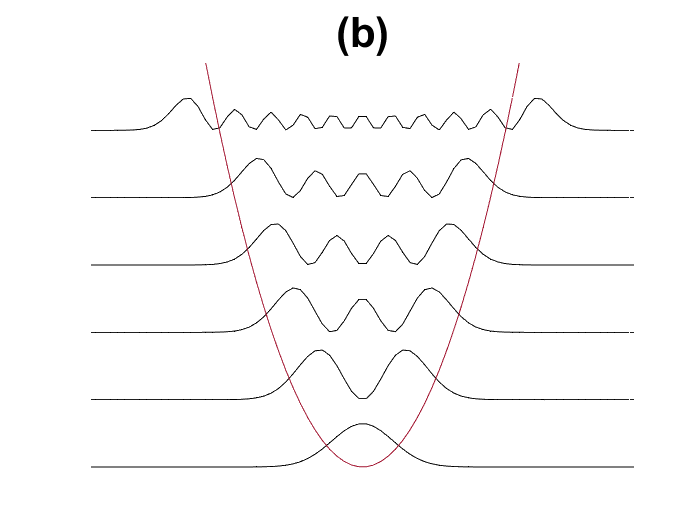

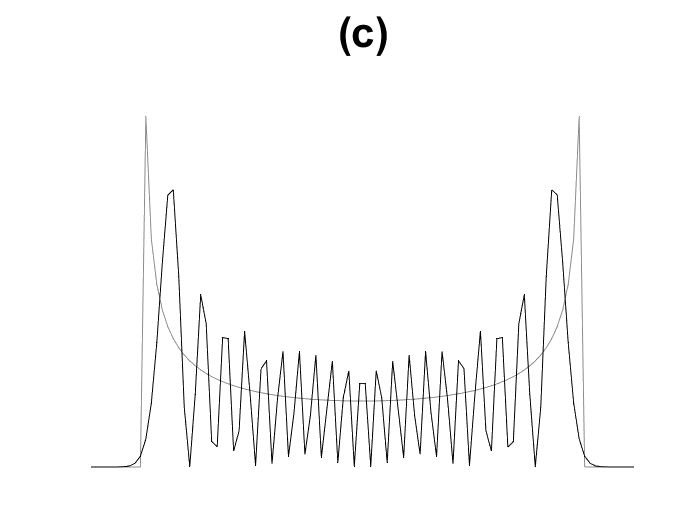

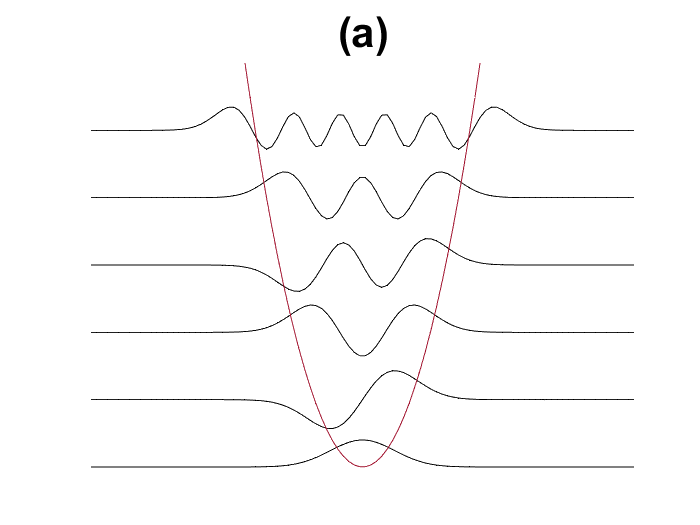

plot(x,z) ; 
ylim([0,6]); set(gca,'XColor','none','YColor','none'); set(gcf,'Visible','on');
curgraph3 = gca ; curgraph3.TitleHorizontalAlignment = 'center';
title ('(a)','FontSize',25)

exportgraphics(curgraph3,'wavefunct.jpg');exportgraphics(curgraph,'wavefunctions.jpg');exportgraphics(curgraph2,'limit.jpg');